clear
load('./traces_v4/input_sets_second_op.mat');

numberOfSets = 110;
setSize = 50;
%Get the mean traces by sets of 50
meanTraces = zeros(numberOfSets,size(traces_Y,2));

for i = 1 : numberOfSets
    meanTraces(i,:)=mean(traces_Y((i-1)*setSize+1:i*setSize,:),1);
end

%Get hamming weights of second operands
hw = hammingWeight(hex2dec(inputs_b(1,:)));

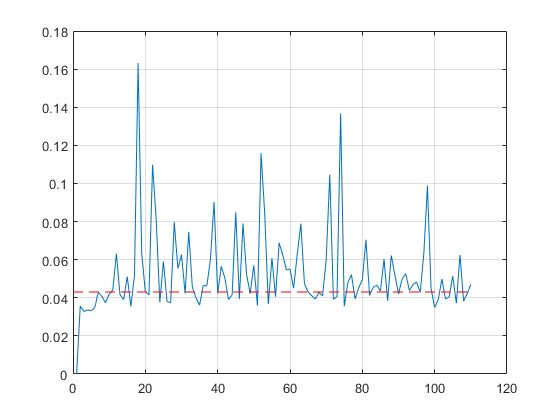


%Calculate euclidean distance with respect to the first average set trace
euclidDistances = zeros(1,numberOfSets);

for i = 1 : numberOfSets
    euclidDistances(i) = norm(meanTraces(1,:)-meanTraces(i,:));
end
plot(euclidDistances)
hold on
line([0 110],[max(euclidDistances(1:10)) max(euclidDistances(1:10))],'Color','red','LineStyle','--')
hold off
grid on


%Calculate accuracy, false positives, false negatives
maxDist = max(euclidDistances(1:10));
falsePos = 0;
falseNeg = 0;
for i = 11 : numberOfSets
    if (euclidDistances(i)<=maxDist)
        if (hammingWeight(hex2dec(inputs_b(i*50,:)))~=hw)
            falsePos = falsePos +1;
        end
    end
end
falsePos

falsePos =     34


falsePosRate = falsePos / (numberOfSets - 10) *100

falsePosRate =     34


for i = 11 : numberOfSets
    if (euclidDistances(i)>=maxDist)
        if (hammingWeight(hex2dec(inputs_b(i*50,:)))==hw)
            falseNeg = falseNeg +1;
        end
    end
end
falseNeg

falseNeg =      9


falseNegRate = falseNeg / (numberOfSets - 10) * 100

falseNegRate =      9



accuracy = (numberOfSets - 10 - falsePos - falseNeg)/(numberOfSets - 10) *100

accuracy =   56.999999999999993


Correlation ?

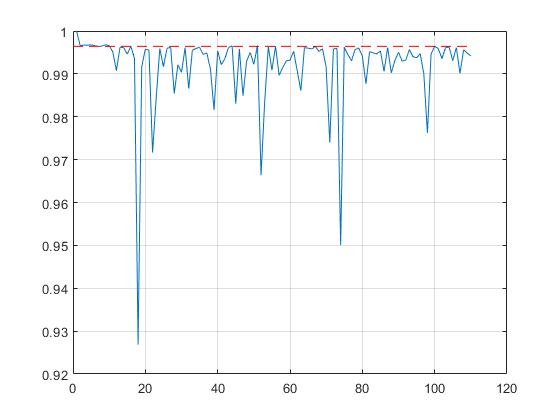

corrs = zeros(1,numberOfSets);
for i = 1 : numberOfSets
    corr = corrcoef(meanTraces(1,:),meanTraces(i,:));
    corrs(i) = corr(1,2);
end
plot(corrs)
hold on
line([0 110],[min(corrs(1:10)) min(corrs(1:10))],'Color','red','LineStyle','--')
hold off
grid on

%Calculate accuracy, false positives, false negatives
minCorr = min(corrs(1:10));
falsePos = 0;
falseNeg = 0;
for i = 11 : numberOfSets
    if (corrs(i)>=minCorr)
        if (hammingWeight(hex2dec(inputs_b(i*50,:)))~=hw)
            falsePos = falsePos +1;
        end
    end
end
falsePos

falsePos =      4


falsePosRate = falsePos / (numberOfSets - 10) *100

falsePosRate =      4


for i = 11 : numberOfSets
    if (corrs(i)<=minCorr)
        if (hammingWeight(hex2dec(inputs_b(i*50,:)))==hw)
            falseNeg = falseNeg +1;
        end
    end
end
falseNeg

falseNeg =     12


falseNegRate = falseNeg / (numberOfSets - 10) * 100

falseNegRate =     12



accuracy = (numberOfSets - 10 - falsePos - falseNeg)/(numberOfSets - 10) *100

accuracy =     84


Bounded collision detection criterion ?

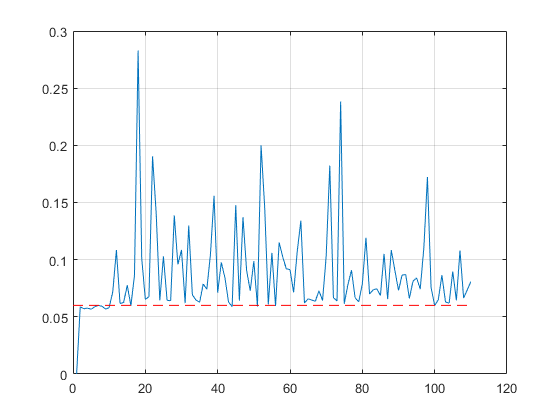

colDet = zeros(1,numberOfSets);
for i = 1 : numberOfSets
    colDet(i) = bcdc(meanTraces(1,:),meanTraces(i,:));
end
plot(colDet)
grid on
line([0 110],[max(colDet(1:10)) max(colDet(1:10))],'Color','red','LineStyle','--')

%Calculate accuracy, false positives, false negatives
maxDet = max(colDet(1:10));
falsePos = 0;
falseNeg = 0;
for i = 11 : numberOfSets
    if (colDet(i)<=maxDet)
        if (hammingWeight(hex2dec(inputs_b(i*50,:)))~=hw)
            falsePos = falsePos +1;
        end
    end
end
falsePos

falsePos =      4


falsePosRate = falsePos / (numberOfSets - 10) *100

falsePosRate =      4


for i = 11 : numberOfSets
    if (colDet(i)>=maxDet)
        if (hammingWeight(hex2dec(inputs_b(i*50,:)))==hw)
            falseNeg = falseNeg +1;
        end
    end
end
falseNeg

falseNeg =     12


falseNegRate = falseNeg / (numberOfSets - 10) * 100

falseNegRate =     12



accuracy = (numberOfSets - 10 - falsePos - falseNeg)/(numberOfSets - 10) *100

accuracy =     84


Use the filtered signal

%Get the mean traces by sets of 50
meanTraces2 = zeros(numberOfSets,size(traces_filt,2));

for i = 1 : numberOfSets
    meanTraces2(i,:)=mean(traces_filt((i-1)*setSize+1:i*setSize,:),1);
end

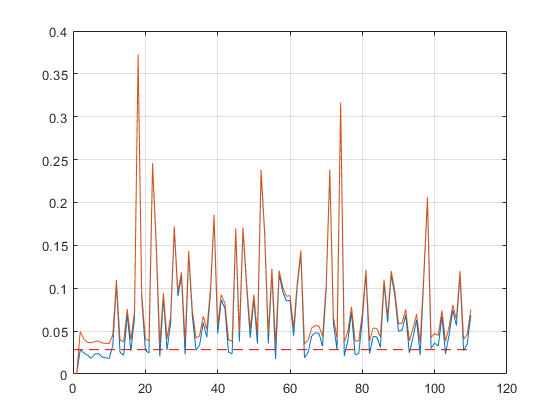

%Calculate euclidean distance with respect to the first average set trace
euclidDistances2 = zeros(1,numberOfSets);

for i = 1 : numberOfSets
    euclidDistances2(i) = norm(meanTraces2(1,:)-meanTraces2(i,:));
end
plot(euclidDistances2)
grid on
hold on
plot(euclidDistances)
line([0 110],[max(euclidDistances2(1:10)) max(euclidDistances2(1:10))],'Color','red','LineStyle','--')
hold off
grid on


%Calculate accuracy, false positives, false negatives
maxDist = max(euclidDistances2(1:10));
falsePos = 0;
falseNeg = 0;
for i = 11 : numberOfSets
    if (euclidDistances2(i)<=maxDist)
        if (hammingWeight(hex2dec(inputs_b(i*50,:)))~=hw)
            falsePos = falsePos +1;
        end
    end
end
falsePos

falsePos =     22


falsePosRate = falsePos / (numberOfSets - 10) *100

falsePosRate =     22


for i = 11 : numberOfSets
    if (euclidDistances2(i)>=maxDist)
        if (hammingWeight(hex2dec(inputs_b(i*50,:)))==hw)
            falseNeg = falseNeg +1;
        end
    end
end
falseNeg

falseNeg =     13


falseNegRate = falseNeg / (numberOfSets - 10) * 100

falseNegRate =     13



accuracy = (numberOfSets - 10 - falsePos - falseNeg)/(numberOfSets - 10) *100

accuracy =     65


Correlation ?

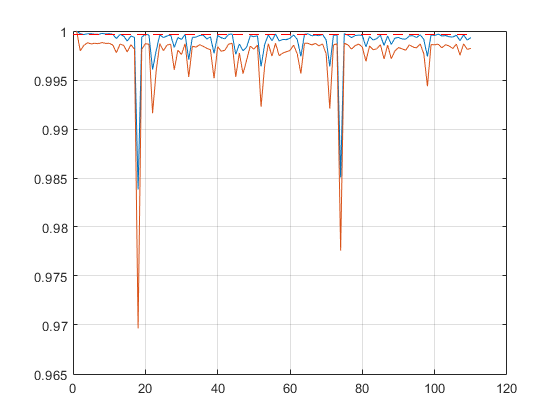

corrs2 = zeros(1,numberOfSets);
for i = 1 : numberOfSets
    corr = corrcoef(meanTraces2(1,:),meanTraces2(i,:));
    corrs2(i) = corr(1,2);
end
plot(corrs2)
hold on 
plot(corrs)
line([0 110],[min(corrs2(1:10)) min(corrs2(1:10))],'Color','red','LineStyle','--')
hold off
grid on

%Calculate accuracy, false positives, false negatives
minCorr = min(corrs2(1:10));
falsePos = 0;
falseNeg = 0;
for i = 11 : numberOfSets
    if (corrs2(i)>=minCorr)
        if (hammingWeight(hex2dec(inputs_b(i*50,:)))~=hw)
            falsePos = falsePos +1;
        end
    end
end
falsePos

falsePos =     10


falsePosRate = falsePos / (numberOfSets - 10) *100

falsePosRate =     10


for i = 11 : numberOfSets
    if (corrs2(i)<=minCorr)
        if (hammingWeight(hex2dec(inputs_b(i*50,:)))==hw)
            falseNeg = falseNeg +1;
        end
    end
end
falseNeg

falseNeg =     12


falseNegRate = falseNeg / (numberOfSets - 10) * 100

falseNegRate =     12



accuracy = (numberOfSets - 10 - falsePos - falseNeg)/(numberOfSets - 10) *100

accuracy =     78


Bounded collision detection criterion ?

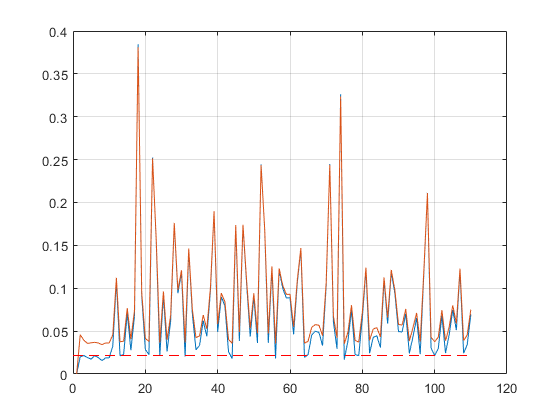

colDet2 = zeros(1,numberOfSets);
for i = 1 : numberOfSets
    colDet2(i) = bcdc(meanTraces2(1,:),meanTraces2(i,:));
end
plot(colDet2)
grid on
hold on 
plot(colDet)
line([0 110],[max(colDet2(1:10)) max(colDet2(1:10))],'Color','red','LineStyle','--')
hold off

%Calculate accuracy, false positives, false negatives
maxDet = max(colDet2(1:10));
falsePos = 0;
falseNeg = 0;
for i = 11 : numberOfSets
    if (colDet2(i)<=maxDet)
        if (hammingWeight(hex2dec(inputs_b(i*50,:)))~=hw)
            falsePos = falsePos +1;
        end
    end
end
falsePos

falsePos =      8


falsePosRate = falsePos / (numberOfSets - 10) *100

falsePosRate =      8


for i = 11 : numberOfSets
    if (colDet2(i)>=maxDet)
        if (hammingWeight(hex2dec(inputs_b(i*50,:)))==hw)
            falseNeg = falseNeg +1;
        end
    end
end
falseNeg

falseNeg =     13


falseNegRate = falseNeg / (numberOfSets - 10) * 100

falseNegRate =     13



accuracy = (numberOfSets - 10 - falsePos - falseNeg)/(numberOfSets - 10) *100

accuracy =     79
